Figures

Dependecies: 

- pangyuteng (2021). Convert Voronoi cells to region mask (https://www.mathworks.com/matlabcentral/fileexchange/43032-convert-voronoi-cells-to-region-mask), MATLAB Central File Exchange. Retrieved April 14, 2021.

Potential issues: 

If script is taking a long time or appears to be stuck, this is likely due to difficulty saving figures. Consider unchecking the "save" option and saving manually instead by opening each figure and using this format from the command line. The '-transparent' option is not needed for vononoi plots or images. the '-m4' option magnifies the figure to improve resolution in the saved file.

export_fig([path, datafile, ' figure name', '.png'], '-m4', '-transparent', gcf); 

% select which plots to run
saveflag = false;
newpath = "";
path = path;

Select which plots to generate:

runRose = true;
runDot =  true;
runMultiDot = true;
genotype = "";
roseRlim = 30;
plotcolor = '#666666';
runVorOverlay = false;
runVorAngle =  false;
runVorOrder =  false;
showColorbar = false;
runColorwheel = false;

If generating a local order plot, select values to calculate the search radius:

numneighbors = 1;
r = 3;

 

Input image

% if any n=1 plots are selected, ask user to select input file. 
if (runRose | runDot | runVorOverlay | runVorAngle | runVorOrder) == true
    % Load data
    cd(userpath)
    [datafile, path] = uigetfile('Images/Maureen/*.mat');
    addpath(path);
    imfile = extractBefore(datafile, ' data');
    imPcad = flip(imrotate(h5read(imfile, '/t0/channel0'), 90),1);
    imSox9 = flip(imrotate(h5read(imfile, '/t0/channel1'), 90),1);
    Data = importdata([path datafile]);

    % Extract key values
    imsize = Data{size(Data,1), 1:2};       % size of original image [x y] stored as last value in follicleData
    % isolate data for all polarized and developed follicles and change angle
    % value for downgrown follicles to -1 to aid visualization (for colormap)
    grown = Data(Data(1:size(Data,1)-1,:).label~=(0), :);
    grown{isnan(grown{:, 4}), 4} = repelem(-1,size(grown{isnan(grown{:, 4}), 4}, 1), 1);
    % separately isolate data for all polarized follicles for rose and dot plots
    polar = Data(Data.label==(1), :);
    % display image
    imshow(imfuse(imadjust(imPcad), imadjust(imSox9)))
end


Dot plot (angle vs A-P position)

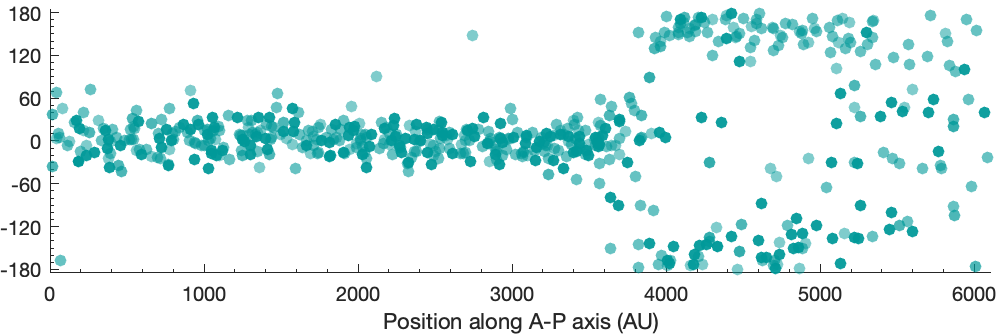

if runDot == true
    % plot of angle by A-P position (x-coord)
    AP = figure;
    scatter(Data{:,1}, Data{:,5},'MarkerFaceColor',plotcolor, 'MarkerEdgeColor',"none", 'MarkerFaceAlpha', .7);
    xlabel('Position along A-P axis (AU)');
    % ylabel('Follicle angle (degrees)');
    yticks(-180:60:180);
    ax = gca;
    ax.YLim = [-185 185];
    ax.XLim = [0 imsize(1)];
    ax.XMinorTick = true;
    ax.YMinorTick = true;
    AP.Position(3:4) = [imsize(1)/imsize(1)*500, imsize(2)/imsize(1)*500];
    outerpos = ax.OuterPosition;
    ti = ax.TightInset; 
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];
    ax.Color = 'none';
    if saveflag == true
        export_fig([path, datafile, ' AP plot', '.png'], '-m4', '-transparent', AP);
    end
end
clf('reset')

if runMultiDot == true
    [multidatafiles, multipath] = uigetfile('Images/Maureen/*.mat', 'MultiSelect', 'on');
    n = length(multidatafiles);
    multiData = cell(n,1);
    AP = figure;
    imsizemulti = [0 0];
    hold on
    for i=1:n
        data = importdata([multipath multidatafiles{i}]);
        if imsizemulti(1) < data{size(data,1), 1}
            imsizemulti(1) = data{size(data,1), 1};
        end
        if imsizemulti(2) < data{size(data,1), 2}
            imsizemulti(2) = data{size(data,1), 2};
        end
        alpha = .9-.1*i;
        scatter(data{:,1},data{:,5},'MarkerFaceColor',plotcolor, 'MarkerEdgeColor',"none", 'MarkerFaceAlpha', alpha);
    end
    xlabel('Position along A-P axis (AU)');
    % ylabel('Follicle angle (degrees)');
    yticks(-180:60:180);
    ax = gca;
    ax.YLim = [-185 185];
    ax.XLim = [0 imsizemulti(1)];
    ax.XMinorTick = true;
    ax.YMinorTick = true;
    AP.Position(3:4) = [imsizemulti(1)/imsizemulti(1)*500, imsizemulti(2)/imsizemulti(1)*500];
    outerpos = ax.OuterPosition;
    ti = ax.TightInset;
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];
    ax.Color = 'none';
    if saveflag == true
        export_fig([path, genotype, sprintf(' AP plot n=%i', n), '.png'], '-m4', '-transparent', AP);
    end
end

Rose plots

if runRose == true
    % % Rose plots by halves
    antData  = Data(Data.xCord<imsize(1)/2, :);
    postData = Data(Data.xCord>imsize(1)/2, :);
    % anterior rose plot
    rose = figure;
    subplot(1,2,1);
    polarhistogram(deg2rad(antData{:,4}), 36, 'BinLimits', [0, 2*pi], 'FaceColor', plotcolor);
    title('Anterior');
    % Posterior rose plot
    subplot(1,2,2)
    polarhistogram(deg2rad(postData{:,4}), 36, 'BinLimits', [0, 2*pi], 'FaceColor', plotcolor);
    title('Posterior');
    % reverse plot direction so 0° aligns w/ anterior and reverse direction of theta increase
    ax = findobj(gcf,'type', 'polaraxes');
    set(ax, 'ThetaZeroLocation', 'left', 'ThetaDir', 'clockwise', 'RLim', [0 30], 'Color', 'none');
    outerpos = rose.OuterPosition;
    rose.Position = [outerpos(1) outerpos(2) outerpos(3)+30 outerpos(4)-250];  % adjust margins
    if saveflag == true
        export_fig([path, datafile, ' rose', '.png'], '-m4', rose, '-nocrop', '-transparent');
    end
    % saveas(rose, [path, datafile, ' rose', '.tif']);
end
clf('reset')

Voronoi overlay

if runVorOverlay == true
    figure;
    imshow(imfuse(imPcad, imSox9));
    hold on;
    h = voronoi(grown{:,1},grown{:,2});
    set(h(1),'Color','none');
    set(h(2), 'Color', 'white');
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
    axis image;
    if saveflag == true
        export_fig([path, datafile, ' voronoi overlay', '.tif'], '-m6', gcf)
    end 
end

if (runVorAngle | runVorOrder) == true
    % create a mask based on voronoi diagrams, using centroids in grown as the seed points
    mask = voronoi2mask(grown{:,1},grown{:,2},[imsize(2), imsize(1)]);
    mask = imerode(mask, [strel('line', 3, 0), strel('line', 3, 90)]);
end

Voronoi angle diagram

if runVorAngle == true
    % define 0:360 angle colormap
    n = 720;        % two colors defined per angle for an even distribution
    % offsets the hsv colormap to center 0° at cyan
    cmap = hsv2rgb(horzcat([(round(n/2):n)./n (0:round(n/2)-1)./n]', repelem(1, n+1)', repelem(1, n+1)'));  % 0° = cyan
    % adds zeros to correspond to negative numbers (ie NaNs, to color black)
    cmap = vertcat([0 0 0; 0 0 0], cmap);
    % creates a masked image with voronoi cells color-coded by angle
    maskcmap = voronoiangle(mask, grown); 
    
    % display voronoi diagram colored by angle
    figure;
    imshow(maskcmap);
    colormap(cmap);
    caxis([-1 360])
    if showColorbar == true
        colorbar
        colorbar('Ticks', [0,.25,.5,.75,1], 'TickLabels', [0,90,180,270,360])
    end 
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
    if saveflag == true
        export_fig([path, datafile, ' voronoi angles', '.tif'], '-m4', gcf)
    end
end

Voronoi order diagram

if runVorOrder == true
    % creates a masked image with voronoi cells color-coded by local order
    % numneighbors is used to calculate ave. distance to the nearest 'numneighbors' neighbors
    % r is the multiple used to calculate the search radius using this
    % average distance. Set both above.
    % search radius = r * ave. distance
    [omaskcmap, avedist, Idx] = voronoiorder(mask, grown, numneighbors, r);
    % display
    figure;
    imshow(omaskcmap);
    colormap(hot)
    if showColorbar == true
        colorbar('Ticks', [0, 1], 'TickLabels', [{'low order'}, {'high order'}])
    end
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
    if saveflag == true
        export_fig([path, datafile, ' voronoi order', '.tif'], '-m4', gcf)
    end
end


% Search radius (magenta) and histogram of neighbors
if runVorOrder == true
    figure; 
    imshow(omaskcmap);
    colormap(hot)
    viscircles([1500, 1000], r*avedist, 'Color', 'magenta');
    %export_fig([path, datafile, sprintf('order r=%i', r), '.tif'], '-m4', gcf)
    ax = histogram(cellfun('length', Idx(:,1))-1, 'NumBins', 5, 'BinEdges', [0:5:100], 'FaceColor', plotcolor);
    title(sprintf('# of neighbors inc. in order calculation using %i*r radius', r));
    % export_fig([path, datafile, ' order r=5 hist', '.tif'], '-m4', gcf)
end 

if runColorwheel == true
    % adapted from color_wheel demo 
    % https://www.mathworks.com/matlabcentral/answers/195913-how-to-make-a-color-wheel-as-colorbar-in-pcolor-fig
    outerRadius = 500;
    innerRadius = 280;		% inner radius of the colour ring
    numberOfSectors = 720;
    grayLevel = 255;
    buffer = 300;
    
    
    [x, y] = meshgrid(-outerRadius-buffer : outerRadius+buffer);
    [theta, rho] = cart2pol(x, y); % theta is an image here.

    % Set up color wheel in hsv space and flip to match axes
    hueImage = (theta + pi) / (2 * pi);     % Hue is in the range 0 to 1.
    hueImage = ceil(hueImage * numberOfSectors) / numberOfSectors;   % Quantize hue
    hueImage = fliplr(flipud(hueImage));

    saturationImage = ones(size(hueImage));      % Saturation (chroma) = 1 to be fully vivid.

    % Make it have the wheel shape.
    % Make a mask 1 in the wheel, and 0 outside the wheel.
    wheelMaskImage = rho >= innerRadius & rho <= outerRadius;
    % Hue and Saturation must be zero outside the wheel to get gray.
    hueImage(~wheelMaskImage) = 0;
    saturationImage(~wheelMaskImage) = 0;
    % Value image must be 1 inside the wheel, and the normalized gray level outside the wheel.
    normalizedGrayLevel = grayLevel / 255;
    valueImage = ones(size(hueImage)); % Initialize to all 1
    valueImage(~wheelMaskImage) = normalizedGrayLevel;	% Outside the wheel = the normalized gray level.

    % Combine separate h, s, and v channels into a single 3D hsv image.
    hsvImage = cat(3, hueImage, saturationImage, valueImage);
    % Convert to rgb space for display.
    rgb = hsv2rgb(hsvImage);
    imshow(rgb);
    fs = 40;
    if showTicks == true
        text(buffer-fs/2, outerRadius+buffer, '0°', 'FontSize', fs, 'HorizontalAlignment', 'right')
        line([buffer, buffer+30], ...
            [outerRadius+buffer outerRadius+buffer], 'Color', 'k', 'LineWidth', 2)
        text(2*outerRadius+buffer, outerRadius+buffer, '180', 'FontSize', fs)
        line([2*outerRadius+buffer-30, 2*outerRadius+buffer], ...
            [outerRadius+buffer outerRadius+buffer], 'Color', 'k', 'LineWidth', 2)
        text(outerRadius+buffer, buffer+fs/4, '90', 'FontSize', fs, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')
        line([outerRadius+buffer, outerRadius+buffer], ...
            [buffer buffer+30], 'Color', 'k', 'LineWidth', 2)
        text(outerRadius+buffer, outerRadius*2+buffer+fs/4, '270', 'FontSize', fs, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top')
        line([outerRadius+buffer, outerRadius+buffer], ...
            [2*outerRadius+buffer-30 2*outerRadius+buffer], 'Color', 'k', 'LineWidth', 2)
    end
    clf('reset')
end

function [maskcmap] = voronoiangle(mask, grown)
maskcmap = mask;
% create heatmap by angle
for i = 1:size(grown, 1)
    maskcmap(maskcmap==i) = grown{i, 4};
end
end


function [omaskcmap, avedist, Idx] = voronoiorder(mask, grown, numneighbors, r)
% Order parameter calculation: uses matrix w downgrown points, but excludes
% from analysis
[~, dist] = knnsearch(grown{:,1:2}, ...
    grown{:,1:2}, 'K', numneighbors+1);                 % find distances to nearest neighbor(s)
avedist = mean(dist(:,2:numneighbors+1), 'all');        % average distance to n nearest neighbors
Idx = rangesearch(grown{grown.label==1,1:2},grown{grown.label==1,1:2},r*avedist);
% associate Idx index with 'grown' table index
k = 1;
for i = 1:(size(grown,1))    
    if grown.label(i)==1    
        Idx{k,2} = i;
        k = k+1;
    end
end
% calculate order parameter
order = zeros([size(grown,1),1], 'double');
for i = 1:size(Idx,1)
        ordertotal = 0;
        for j = 2:size(Idx{i,1},2)
            ordertotal = ordertotal + ...
                (cosd(grown{Idx{i,2},4} - grown{Idx{Idx{i,1}(j), 2},4})+1)./2;
        end 
        order(Idx{i,2}, 1) = ordertotal./(size(Idx{i,1},2)-1);
end
% convert labels in mask to the order value
omaskcmap = mask;
for i = 1:size(grown, 1)
    omaskcmap(omaskcmap==i) = order(i, 1);
end
end